# Some examples for the application of remezex()

Execution date

datetime("today")

ans = datetime
   04-Aug-2024


## Example 1: exp() on a small interval

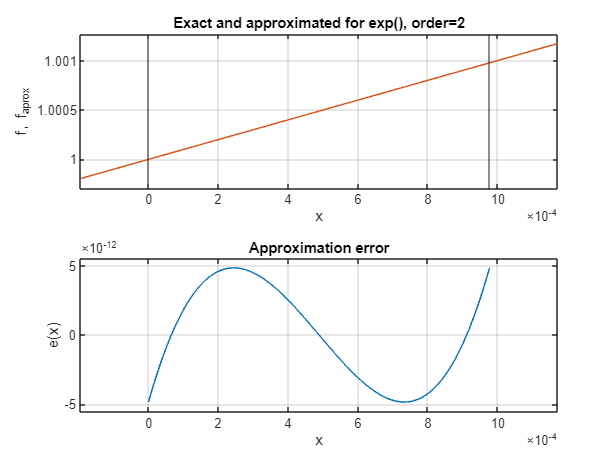

fun_str  = "exp()";
fun      = @(x) exp(x);
fun_der  = @(x) exp(x);
interval = [0, 2^(-10)];
order    = 2;
[p, ~] = remezex(fun, fun_der, interval, order, 'multi', true);
plot_demo(fun, fun_str, p, interval);

## Example 2: exp() on a large interval

interval = [-8 0];
order    = 5;
[p, ~] = remezex(fun, fun_der, interval, order, 'multi', true, 'verbosity', 2);

*** Start of iteration 1 ***
Polynomial coefficients: 
0.000311452, 0.00786996, 0.077511, 0.377059, 0.934437, 0.994505
Error: 0.005495
Error function root #1 in interval [-8, -7.4837]: -7.8482
Error function root #2 in interval [-7.4837, -5.8682]: -6.6874
Error function root #3 in interval [-5.8682, -4.1862]: -4.8463
Error function root #4 in interval [-4.1862, -2.0179]: -2.6081
Error function root #5 in interval [-2.0179, -0.54859]: -0.95375
Error function root #6 in interval [-0.54859, 0]: -0.1019
Extremum #1 in interval [-8, -7.8482] at -8 with error 0.005495
Extremum #2 in interval [-7.8482, -6.6874] at -7.3959 with error 0.0056605
Extremum #3 in interval [-6.6874, -4.8463] at -5.8075 with error 0.0055234
Extremum #4 in interval [-4.8463, -2.6081] at -3.6884 with error 0.0071204
Extremum #5 in interval [-2.6081, -0.95375] at -1.7052 with error 0.0065246
Extremum #6 in interval [-0.95375, -0.1019] at -0.42746 with error 0.0060083
Extremum #7 in interval [-0.1019, 0] at 0 with error 

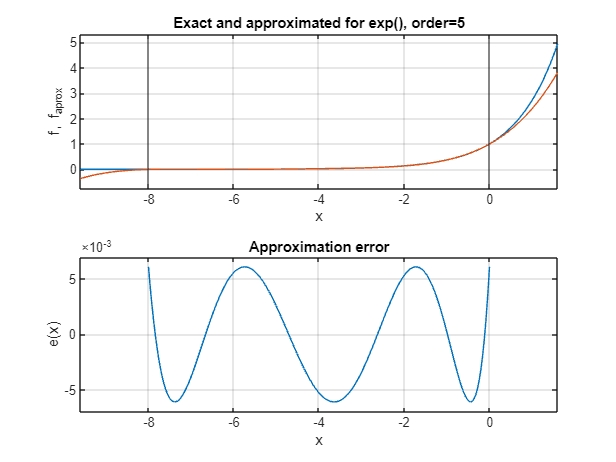

plot_demo(fun, fun_str, p, interval);

## Example 3: sin() on small interval

fun_str  = "sin()";
fun      = @(x) sin(x);
fun_der  = @(x) cos(x);
interval = [0, 2^(-10)];
order    = 2;
[p, ~] = remezex(fun, fun_der, interval, order, 'verbosity', 1);

*** Start of iteration 1 ***
Shifting x(3)=0.00074684 by -1.4312e-05
*** Start of iteration 2 ***
Shifting x(2)=0.00025711 by -1.2909e-05
*** Start of iteration 3 ***
Shifting x(3)=0.00073252 by -1.0185e-07
*** Start of iteration 4 ***
Shifting x(2)=0.0002442 by -5.5892e-08
*** Start of iteration 5 ***
Best approximation polynomial of order 2 over [0, 0.00097656] with max abs error 4.8506e-12:
-2.441406089701559e-04 * x^2
+1.000000089406958e+00 * x^1
-4.850637758801613e-12


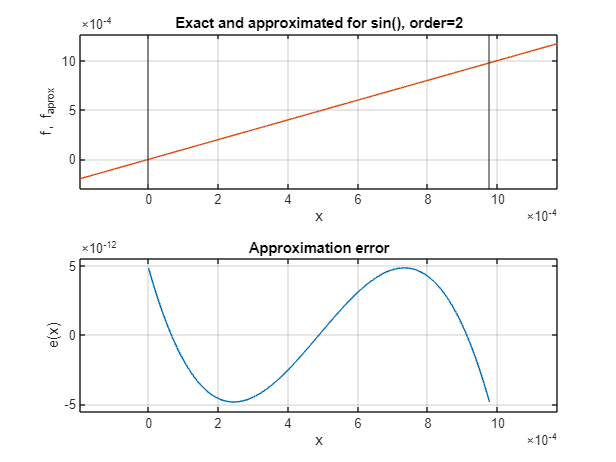

plot_demo(fun, fun_str, p, interval);

## Example 4: sin() on large interval

Usually, the approximation of sin over more than interval $0 \ldots \pi/2$ is never needed as all sections of sin, cos may be reconstructed by argument shifting and function value negation.

A 5th order approximation on $0 \ldots \pi/2$ results in a maximal error of $7.0685 \cdot 10^{-6}$

interval = [0 pi/2];
order    = 5;
[p, E] = remezex(fun, fun_der, interval, order, 'verbosity', 0);
disp("Maximal approximation error: " + E);

Maximal approximation error: 7.0685e-06


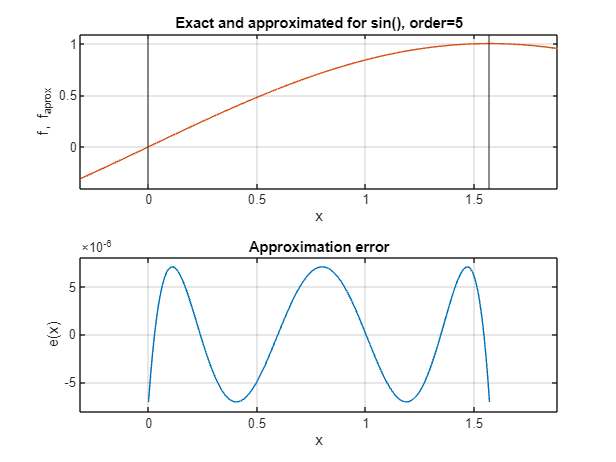

plot_demo(fun, fun_str, p, interval);

As a comparison, consider the approximation to the even function section over $-\pi/2 \ldots \pi/2$.  For the same polynomial order the error is an order of magnitude greater ($6.7706 \cdot 10^{-5}$) than those for $0 \ldots \pi/2$. This can be explained because only the even powers can now contribute to the approximation which lowers the degree of freedoms of the approximation:

interval = [-pi/2 pi/2];
order    = 5;
[p, ~] = remezex(fun, fun_der, interval, order, 'verbosity', 0);
disp("Maximal approximation error: " + E);

Maximal approximation error: 7.0685e-06


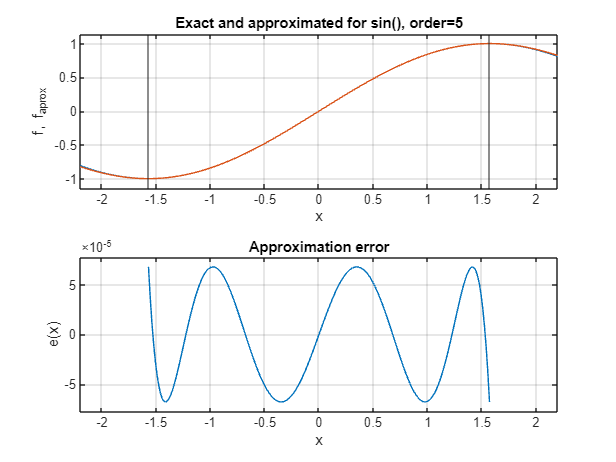

plot_demo(fun, fun_str, p, interval);

With an order of 7, the maximal error reduces to $5.8915 \cdot 10^{-7}$, which is an order of magnitude smaller compared to the 5th order approximation over $0 \ldots \pi/2$. 

interval = [-pi/2 pi/2];
order    = 7;
[p, E] = remezex(fun, fun_der, interval, order, 'verbosity', 0);
disp("Maximal approximation error: " + E);

Maximal approximation error: 5.8915e-07


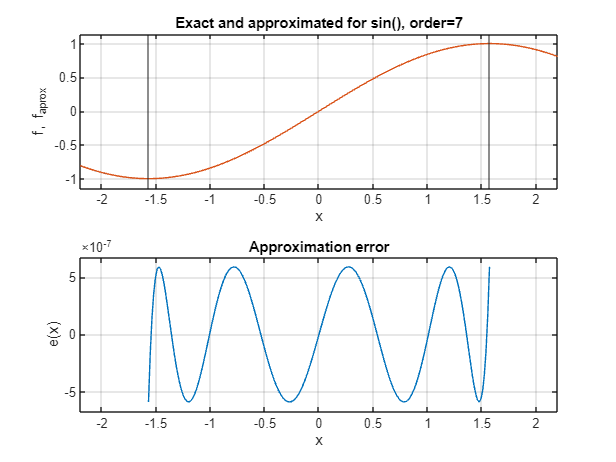

plot_demo(fun, fun_str, p, interval);

Due to the even symmetry the computation of this 7th order approximation can be implemented with the Horner scheme using only 5 multiplications using 4 coefficients:


$$a_1 x + a_3 x^3 + a_5 x^5 + a_7 x^7
=
x \left(
a_1 + x^2
\left(
a_3 + x^2
\left(
a_5 + a_7 x^2
\right)
\right)
\right)$$


The Horner scheme for a general 5th order polynomial with 6 coefficients needs also 5 multiplications.

This shows that employing the function even/odd symmetry may have computational benefits even if you have to enlarge the approximation interval or the polynomial order.

## Example 5: atan()

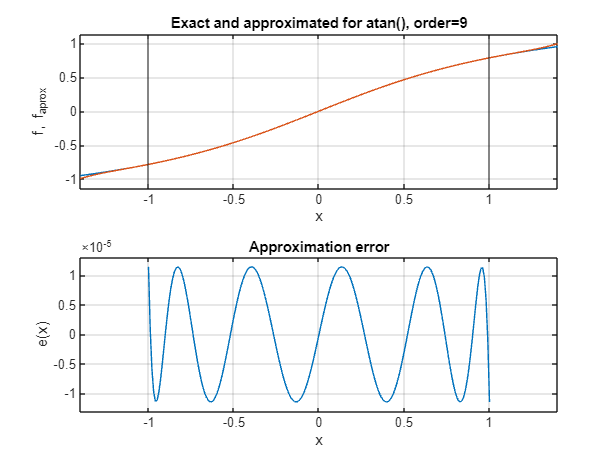

fun_str  = "atan()";
fun      = @(x) atan(x);
fun_der  = @(x) 1./(x.^2+1);
interval = [-1 1];
order    = 9;
[p, ~] = remezex(fun, fun_der, interval, order);
plot_demo(fun, fun_str, p, interval);

## Helper function

function plot_demo(fun, fun_str, p, interval)
    numTestPoints = 200;
    order = numel(p)-1;
    iv_full = [ ...
        interval(1) - (interval(2)-interval(1))/5, ...
        interval(2) + (interval(2)-interval(1))/5 ];
    % fitting range
    x_fit = linspace(interval(1), interval(2), numTestPoints);
    % full plotting range range
    x_full = linspace(iv_full(1), iv_full(2), numTestPoints);
    e = fun(x_fit) - polyval(p, x_fit);
    figure();
    tiledlayout('vertical');
    nexttile;
    % plotting the function and the approximation
    plot(x_full, fun(x_full), x_full, polyval(p, x_full));
    xline(interval(1)); xline(interval(2));
    xlim(iv_full); ylim('padded');
    xlabel('x'); ylabel('f, f_{aprox}'); grid on;
    title("Exact and approximated for " + fun_str + ", order=" + order);
    % plotting the approximation error over the approximation interval
    nexttile;
    plot(x_fit, e);
    xlim(iv_full); ylim('padded');
    xlabel('x'); ylabel('e(x)'); grid on;
    title("Approximation error");
end